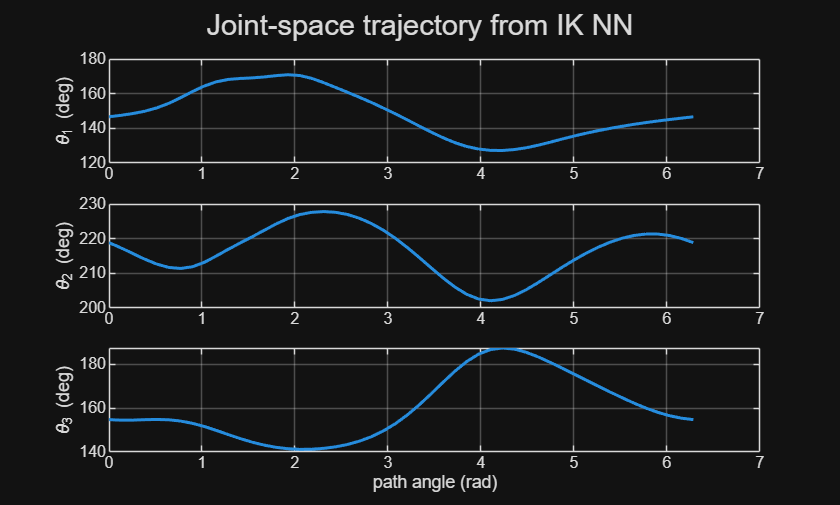

clc; clear; close all;
load('Inverse_Kinematics_Model.mat','net');

data = readtable('arm_workspace_points.csv');
data = data(data.theta3_deg < 175, :);
c  = [data.x_mm(1); data.y_mm(1); data.z_mm(1)]; %pick a reachable point c
q4 = data.q4_mm(1);

% task-space trajectory: 3D figure 8 (lemniscate of Gerono)
R = 75; M = 50;
s = linspace(0, 2*pi, M);
path = c + R*[sin(s); sin(s).*cos(s)*cos(pi/6); sin(s).*cos(s)*sin(pi/6)];

% IK NN: x,y,z -> joint variables
Q = net([path; q4*ones(1,M)]);

% plot joint space
figure;
subplot(3,1,1); plot(s,Q(1,:),'LineWidth',1.5); ylabel('\theta_1 (deg)'); grid on
subplot(3,1,2); plot(s,Q(2,:),'LineWidth',1.5); ylabel('\theta_2 (deg)'); grid on
subplot(3,1,3); plot(s,Q(3,:),'LineWidth',1.5); ylabel('\theta_3 (deg)'); grid on
xlabel('path angle (rad)'); sgtitle('Joint-space trajectory from IK NN');

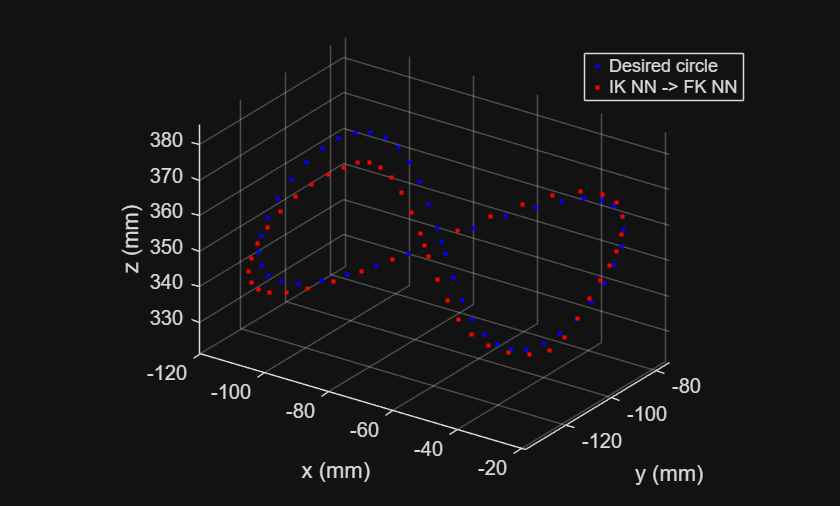


%now, run the joint space through the fk network to get the task space
fk = load('Forward_Kinematics_Model.mat').net;
P = fk([Q; q4*ones(1,M)]);               % FK net: joints -> x,y,z

%plot the output task space trajectory vs input task space trajectory
figure; hold on; grid on; axis equal
plot3(path(1,:),path(2,:),path(3,:),'b.','LineWidth',1); %input
plot3(P(1,:),P(2,:),P(3,:),'r.','LineWidth',1); %output
legend('Desired circle','IK NN -> FK NN');
xlabel('x (mm)'); ylabel('y (mm)'); zlabel('z (mm)'); view(35,25)


%error calc
e = vecnorm(P - path, 2, 1);
fprintf('Tip error: mean %.2f mm, max %.2f mm\n', mean(e), max(e));

Tip error: mean 4.77 mm, max 10.74 mm



writematrix(Q', 'joint_trajectory.csv');
q4_tick = 1254 + (q4 - 60) * (2048 - 1254) / 38.8;
ticks_all = [round(Q * (4096/360)); round(q4_tick)*ones(1,M)];
writematrix(ticks_all', 'joint_trajectory_ticks.csv');